# Digital Modulations

Poiché le modulazioni viste a lezione hanno proprietà in comune e possono essere descritte in base al numero M di simboli e all'energia media dei segnali, ho deciso di raggruppare le funzioni e i campi condivisi da esse in un'unica classe astratta, DigitalModulation.

PAM e PPM sono sottoclassi dirette di DigitalModulation, mentre PSK e PPM sono sottoclassi di BidimensionalDigitalModulation, a sua volta sottoclasse di DigitalModulation. BDM racchiude la possibilità di rappresentare su grafico la simulazione Monte Carlo (poiché bidimensionale). Anche PAM ha questa proprietà, realizzata in modo leggermente diverso.

pam = PAM(16, 30);
ppm = PPM(16, 30);
psk = PSK(16, 30);
qam = QAM(16, 30);

pam.displayProperties();

M: 16
AverageEnergy: 30.000000
Dimensionality: 1


ppm.displayProperties();

M: 16
AverageEnergy: 30.000000
Dimensionality: 16


psk.displayProperties();

M: 16
AverageEnergy: 30.000000
Dimensionality: 2


qam.displayProperties();

M: 16
AverageEnergy: 30.000000
Dimensionality: 2


Ciascuna modulazione deve concretizzare dei metodi astratti di DigitalModulation, che devono essere specifici per ciascuna di esse. In particolare, dimensionality(), errorProbability() e signalCoords(). Quest'ultimo restituisce le coordinate geometriche di ciascun segnale, e.g.:

pam.signalCoords()

ans =    -8.9113
   -7.7232
   -6.5350
   -5.3468
   -4.1586
   -2.9704
   -1.7823
   -0.5941
    0.5941
    1.7823


ppm.signalCoords()

ans =     5.4772         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    5.4772         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    5.4772         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    5.4772         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    5.4772         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0    5.4772         0         0         0         0         0         0         0         0         0         0
         0         0        

Altri metodi di utlità di DigitalModulation consistono nella possibilità di gestire energia media e energia per bit separatamente, scegliendo se basarsi su una o sull'altra.

pam.setBitEnergy(10);
pam.averageEnergy

ans = 40

pam.setMKeepBitEnergy(10);
pam.averageEnergy

ans = 33.2193

pam.setMKeepAverageEnergy(16);
pam.averageEnergy

ans = 33.2193

Come già detto, le modulazioni PAM, PSK e QAM offrono la possibilità di rappresentare la simulazione Monte Carlo:

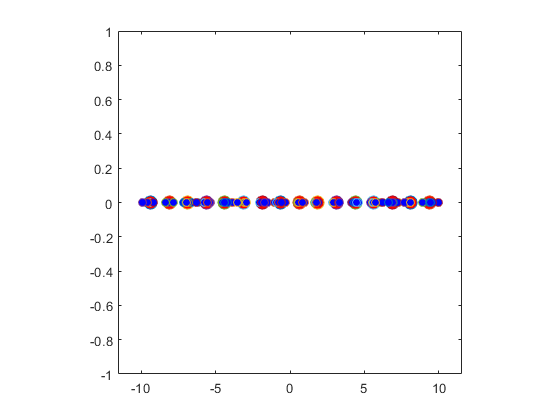

pam.drawMontecarloSim(0.1, 100);

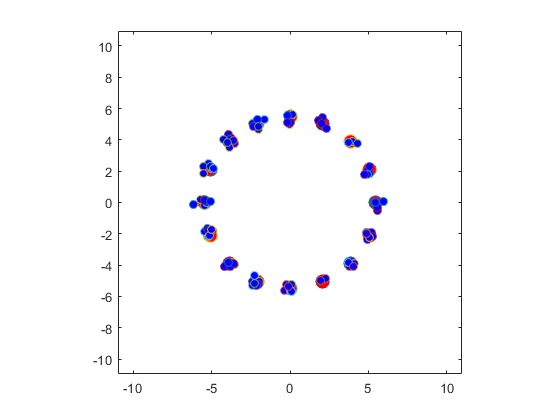

psk.drawMontecarloSim(0.1, 100);

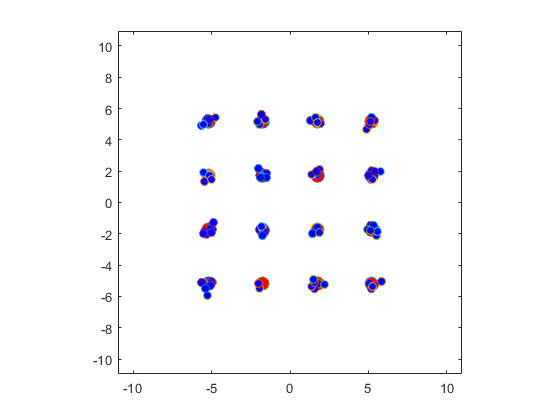

qam.drawMontecarloSim(0.1, 100);

La QAM non deve per forza essere quadrata: il metodo signalCoords() si autogestisce per qualunque M dato.

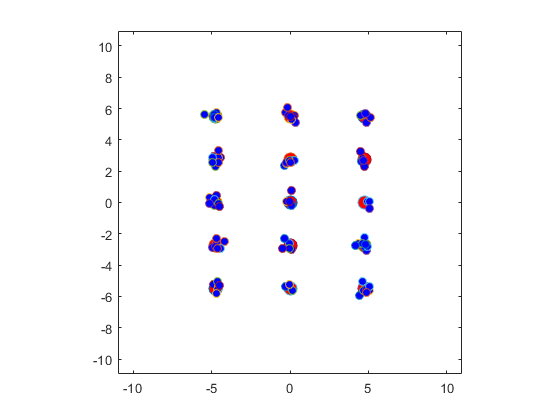

qam.setMKeepAverageEnergy(15);
qam.drawMontecarloSim(0.1, 100);

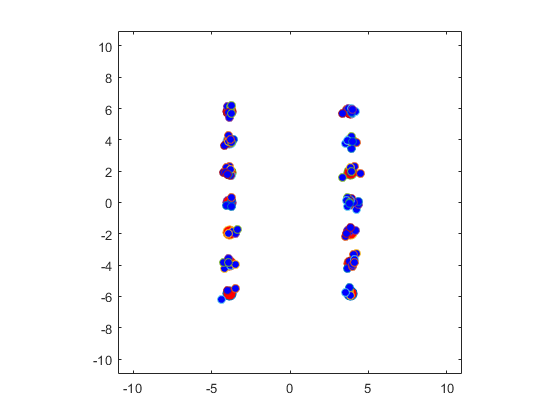

qam.setMKeepAverageEnergy(14);
qam.drawMontecarloSim(0.1, 100);

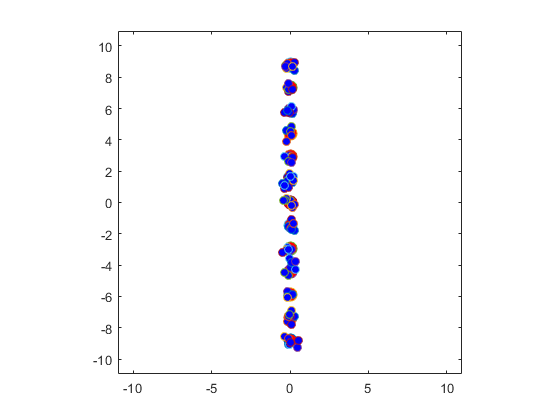

qam.setMKeepAverageEnergy(13);
qam.drawMontecarloSim(0.1, 100);

Infine, ho aggiunto un metodo errorProbability() a ciascuna delle classi. Esso ha funzioni leggermente diverse in base alla modulazione su cui viene invocato: per PSK e PPM restituisce un upper bound della probabilità d'errore, mentre per QAM e PAM restituisce la probabilità esatta (ciò è specificato da se è alto o meno il secondo parametro restituito dalla funzione). Nel caso della QAM il metodo calcola la probabilità a partire dalle 2 PAM in larghezza e lunghezza.

qam.errorProbability(1)

ans = 0.2775

[~, errorRatio] = qam.montecarloSim(1, 100000);errorRatio % Risultato sperimentale

errorRatio = 0.2773